# Labb 3

## 3

clear; clc;
s = tf('s');

[J, umax] = lab3robot(010621);


Loaded from lab3robot:



fprintf('  J     = %.6f\n', J);

  J     = 5.500000


fprintf('  umax  = %.6f\n\n', umax);

  umax  = 80.000000




% =========================================================
%  Systemparametrar
% =========================================================
Lm   = 2;
Rm   = 21;
b    = 1;
Ktau = 38;
Km   = 0.5;
n    = 1/20;


## 3.1 

% Ass 1, överföringsfunktion 
% =========================================================
num = n * Ktau;   %Täljare
den = ((((s * Lm) + Rm) * ((J * s) + b)) + (Ktau * Km)) * s;  %Nämnare
G = num / den  % överföringsfukntion

G =
 
             1.9
  -------------------------
  11 s^3 + 117.5 s^2 + 40 s
 
Continuous-time transfer function.
Model Properties


lab3robot(G, 010621);  % testar om korrekt G

System transfer function G is correct


% =========================================================


## 3.2  P-control

% Ass 2,3 Testa P-regulator på robotens G(s)
clc
K = 3.75;   % ändra detta tills overshoot < 5%

Go = K*G;   % öppen loop
%T = feedback(Go,1); %sluten loop
Gc = (G*K)/(1+ (G*K));   %sluten loop % samma som T = feedback(L,1);

disp('----- 3.2 -----')

----- 3.2 -----



% info om systemet
stepinfo(Gc)

ans = struct with fields:
         RiseTime: 8.3854
    TransientTime: 24.0445
     SettlingTime: 24.0445
      SettlingMin: 0.9088
      SettlingMax: 1.0498
        Overshoot: 4.9763
       Undershoot: 0
             Peak: 1.0498
         PeakTime: 17.5816


[GM, PM, Wcg, Wcp] = margin(Go)   % [gainmargin (dB), fasmarginal (grader), crossover freq, där fasen är -180 (rad/s), skärfrekvens (rad/s)]

GM = 59.9681

PM = 64.4146

Wcg = 1.9069

Wcp = 0.1618

Wb = bandwidth(Gc)

Wb = 0.2558


% %--- Step-function ---
% figure; step(Gc)
% title(sprintf('Closed-loop step response (K = %.2f)', K));
% grid on;
% 
% % --- bode-plots ---
% figure; margin(Go); grid on;
% title('Open-loop Bode with margins');
% 
% nyquist(Go);

## 3.3 Improved control

disp('----- 3.3 -----')

-----3.3-------


Wc = 0.1618;              % skärfrekvens från P-control
Wc_ny = 4 * Wc            % Wc x 4 för att göra systemt 4x snabbare

Wc_ny = 0.6472



phi_Wc_ny = -155 ;                                     % undersöker plot för GK, eftersom vi vill ha 4 x Wc från P-kontroller
phi_wish = 65     ;                                    % vill ha ca. 65 grader för M = 5% ungefär
phi_tot = -180 + phi_wish;
phi_max = phi_tot - phi_Wc_ny + 5.7  + 3;              % önskat faslyft,  + 5.7 eftersom lag-part + 3 för ännu störrefaslyft -> mindre OS och Tr
phi_max_rad = deg2rad(phi_max);

% 
beta = (1 - sin(phi_max_rad))/(1 + sin(phi_max_rad))   % beta från diagram eller med denna funktion

beta = 0.1420

tauD = 1/(Wc_ny*sqrt(beta))                            % standrad för tauD

tauD = 4.0999

tauI = 15 / Wc_ny                                      % utgå från 10 

tauI = 23.1768


% K-värde
FG_amp_dB = -20.4;                                     % undersök bodeplot
FG_amp = 10^(FG_amp_dB/20);                            % ger vilket K som ger önskad Wc som nu passar med önskat phi_m = phi_wish
K_lead_lag = 1 / FG_amp 

K_lead_lag = 10.4713

K_lead_lag = 11;                                       % ökar K lite för snabbare system, ungefär som det beräknade

%lead
lead = (tauD*s + 1)/(beta*tauD*s + 1);
%lag
gamma = 0.025;                                         % bestämmer bidrag från lag-del, gamma = 0 oändligt lågfrekvensförsträkning, vill va nära 0 för att minska felet
lag = (tauI*s + 1) / (tauI*s + gamma);

% Lead-lag-regulatorn F
F = minreal(K_lead_lag * lead * lag)

F =
 
  77.45 s^2 + 22.23 s + 0.8151
  ----------------------------
    s^2 + 1.718 s + 0.001852
 
Continuous-time transfer function.
Model Properties



Go = F * G;                                            % öppen loop
Gc = Go / (1+Go);                                      % stängd loop


% beräkna u(t) (spänningen) måste se till att den ej  överstiger umax = 80,
% K och höjt faslyft ökar u.
[y, t] = step(Gc);
U = feedback(F,G);     % r-> F -> G -> y
U = F / (1 + (F*G));
[u,t] = step(U);       % u = F_lead_lag*(1 - y)
umax;
Umax = max(u)

Umax = 77.4472


% beräknar felet
Kv = dcgain(s*Go);
ess = 1/Kv     % < 0.05

ess = 0.0478


% info om systemet
stepinfo(Gc)

ans = struct with fields:
         RiseTime: 2.0554
    TransientTime: 36.4973
     SettlingTime: 36.4973
      SettlingMin: 0.9085
      SettlingMax: 1.0428
        Overshoot: 4.2767
       Undershoot: 0
             Peak: 1.0428
         PeakTime: 14.9423


[GM, PM, Wcg, Wcp] = margin(Go);   % [gainmargin (dB), fasmarginal (grader), crossover freq, där fasen är -180 (rad/s), skärfrekvens (rad/s)]

GM = 16.7164

PM = 69.3896

Wcg = 4.3045

Wcp = 0.6621

disp(['Fasmarginal phi_m = ' num2str(PM)])

Fasmarginal phi_m = 69.3896


Wb = bandwidth(Gc);

% %--- step-function ---
% figure; step(Gc)
% title(sprintf('Closed-loop step response (K = %.2f)', K));
% grid on;
% 
% % --- bodeplots ---
% figure; margin(Go); grid on;
% title('Open-loop Bode with margins');
% 
% nyquist(Go);


## 3.4 Sensitivity

% Ass 8
disp(['----- 3.4 -----'])

----- 3.4 -----


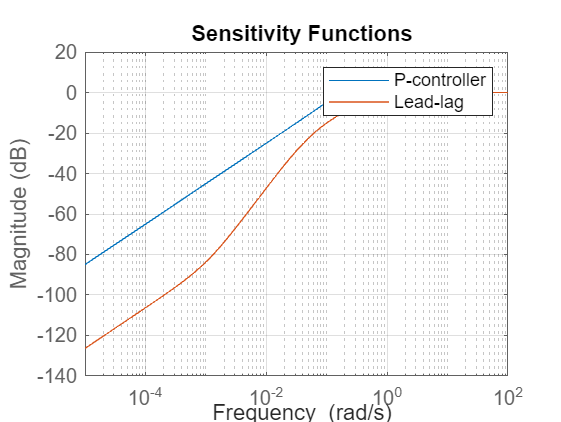

S1 = minreal(1 /(1 + (G * K)));
S2 = minreal(1 / (1 + (G * F)));

bodemag(S1,S2)
legend('P-controller', 'Lead-lag');
title('Sensitivity Functions');
grid on;

## 3.5 robustness

%Ass 9
disp(['----- 3.5 -----'])

----- 3.5 -----


detla_G1 = (s +10) / 40;
detla_G2 = (s +10) / (4*(s +0.01));

% nya G med modellfel
G1 = G * (1 +detla_G1);
G2 = G * (1 + detla_G2);

% komplementära känslighetsfunktionen 
T1 = F * G1 / (1 + F * G1);       
T2 = F * G2 / (1 + F * G2);

% figure; bodemag(T1, T2)
% legend('T1', 'T2')
% 
% % koll step-functions
% Gc1 = F_lead_lag * G1 / (1 + F_lead_lag*G1);
% figure; step(Gc1)
% Gc2 = F_lead_lag * G2 / (1 + F_lead_lag*G2);
% figure; step(Gc2)   %Gc2 ostabil



## 3.6 State space model 3.7 Pole placement

disp(['----- 3.6 State space model -----'])

----- 3.6 State space model -----


% Ass 10 (gjord för hand också med styrbar kanonisk form)

num = 1.9/11;               % delar nämn o tälj med 11 för att få på rätt form
den = [11 117.5 40 0]/11;   % a3=1, a2=10.68, a1=3.636, a0=0
[A,B,C,D] = tf2ss(num, den) 

A =   -10.6818   -3.6364         0
    1.0000         0         0
         0    1.0000         0


B =      1
     0
     0


C =          0         0    0.1727


D = 0



% Ass 11 kontrollerbart och observerbart

S = [B, A*B, A^2*B]; % S = kontrollbarhetsmatrisen, ska vara av rang n i nxn-matris
detS = det(S)   % ska vara nollskild

detS = 1


O = [C; C*A; C*A^2];  % O = observerbarhetsmatrisen, ska vara av rang n i nxn-matris
detO = det(O)   % ska vara nollskild

detO = -0.0052



% 3.7 
disp(['----- 3.7 Pole placement -----'])

----- 3.7 Pole placement -----



% om man ska göra för hand:
% syms l1 l2 l3
% L = [l1, l2, l3];
% Ac = (A - B*L);
% detAc = det(eye(3)*s-Ac) 

% Ass 12

% beräkna först L

% parametrar för poler med im-del
psi = 0.7; 
w0  = 1.5;           %Tr = 1.8/w0

% poler
p1 = (-psi*w0) + (j*w0*sqrt(1-psi^2))

p1 = -1.0500 + 1.0712i

p2 = conj(p1);
p3 = -4;             % kan ändra på, re-pol ska ligga ungefär 4x till vänster från konj.par
P = [p1 p2 p3];

% L och ny A-matris Ac
L = place(A, B, P)   % beräknar L med önskade poler

L =    -4.5818    7.0136    9.0000


Ac = (A - B*L);

% beräkna l0

l0 = - 1 / (C*(Ac)^-1*B)   %Enligt teori   %l0 = 1 / dcgain(sys)

l0 = 52.1053


% Closed loop tf/överföringsfunktion
Gc = ss(Ac, B*l0, C, D);

% Kolla DC-gain (statisk förstärkning)
dc_gain = dcgain(Gc);   % om 1, betyder att systemet nått steady-state r = y (inget statiskt fel) vi väljer l0 utifrån detta
fprintf('DC gain: %.4f (should be 1.000)\n', dc_gain);

DC gain: 1.0000 (should be 1.000)



% System från r till u: u = -Lx + l0*r
sys_u = ss(Ac, B*l0, -L, l0);
[u,t] = step(sys_u);
u_max = max(abs(u));
fprintf('Max |u(t)|: %.3f (umax = %.3f)\n', u_max, umax);

Max |u(t)|: 72.359 (umax = 80.000)



%Info om systemet
info = stepinfo(Gc);
fprintf('Tr=%.3fs, Mp=%.1f%',info.RiseTime, info.Overshoot);

Tr=1.526s, Mp=4.2

figure; step(Gc);grid





lab3robot(G,K, F,A,B,C,L,l0,010621)